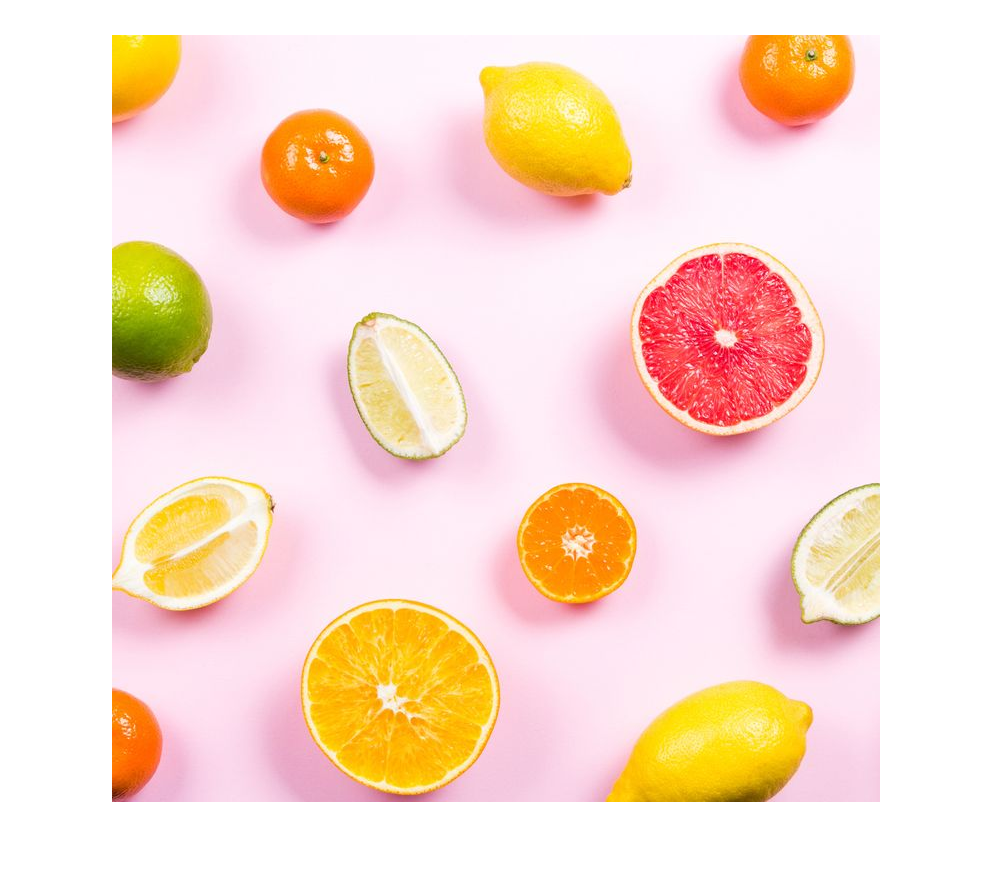

close all; % it's a good practice to initialize the environment at the beginning of each code
clear;
%% Question 1,1
img_fruit = imread("fruits.jpg"); % read the image in current folder
imshow(img_fruit); % display the original image

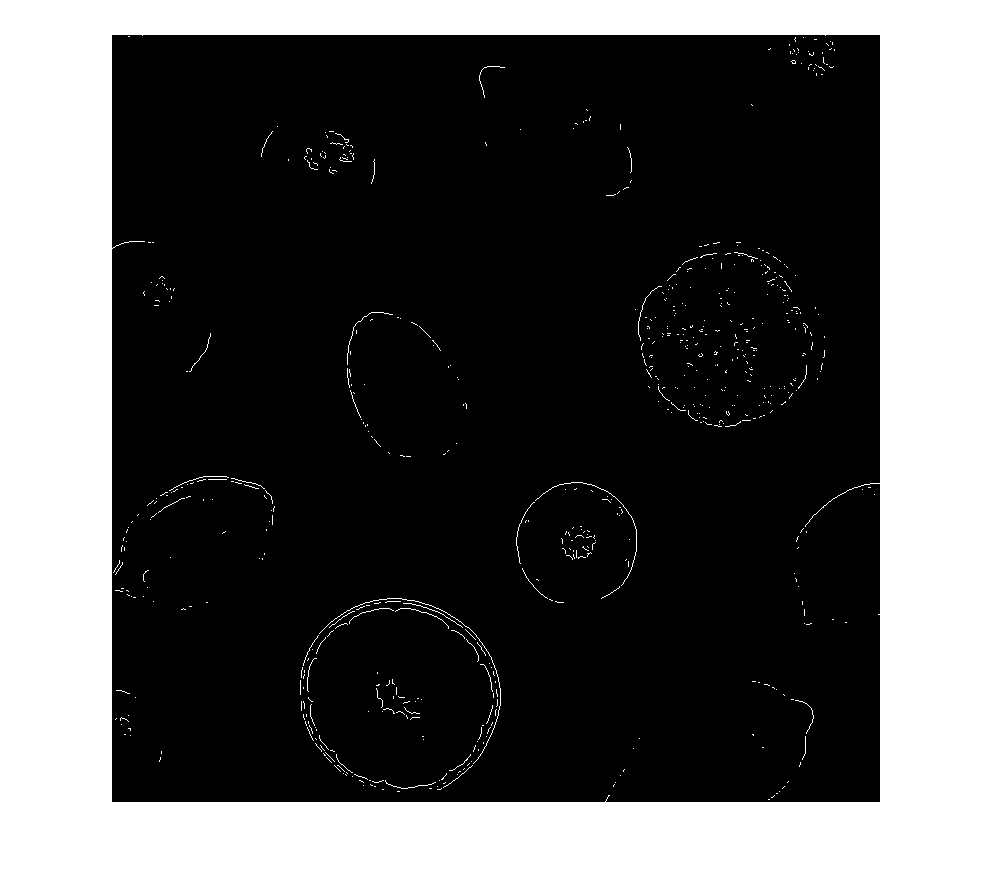

img_fruit_blue = img_fruit(:, :, 3); % extract the blue channel from the image
img_fruit_sobel = edge(img_fruit_blue, 'sobel', 0.2); % use sobel edge detection
imshow(img_fruit_sobel); % display the detected edges

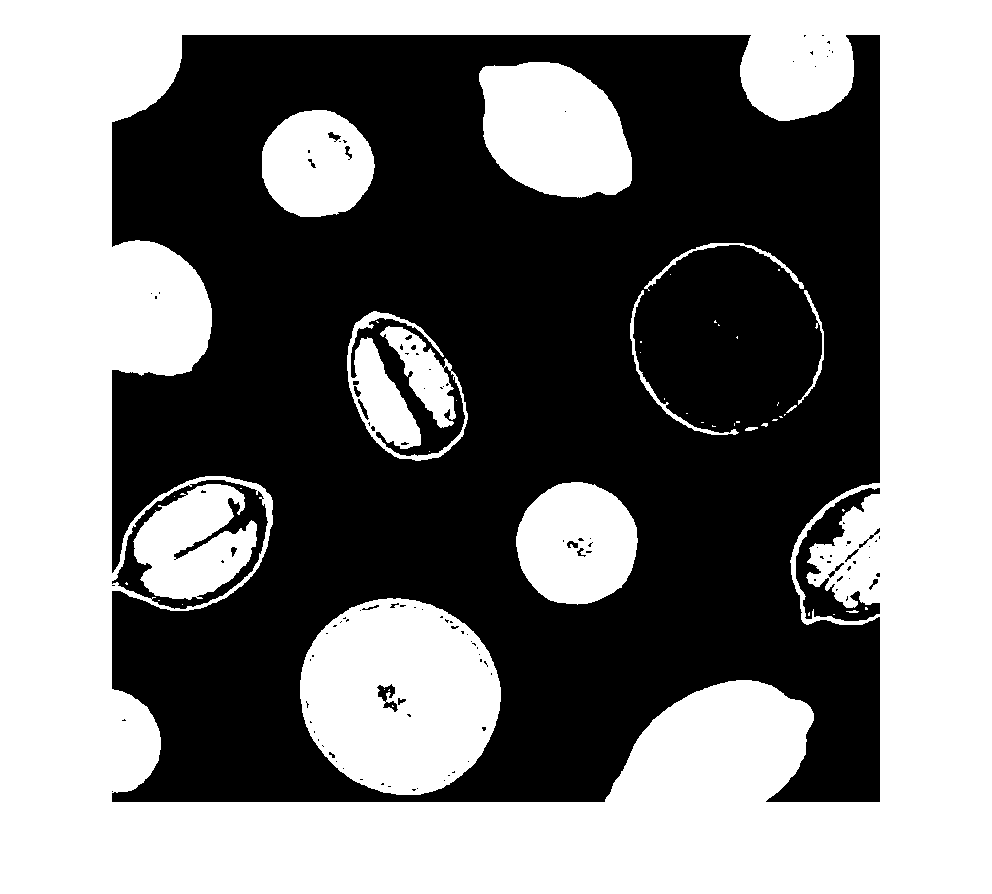

%% Question 1.2
img_fruit_green = img_fruit(:, :, 2); % extract the green channel from the image
img_diff = abs(img_fruit_green - img_fruit_blue); % calculate the difference of intensity between blue and green channel
img_diff2 = img_diff > 30; % binarize the image base on the difference
img_diff3 = imbinarize(img_diff, 30/255); % this line has similar effect to the previous line
imshow(img_diff2); % display the binarized image

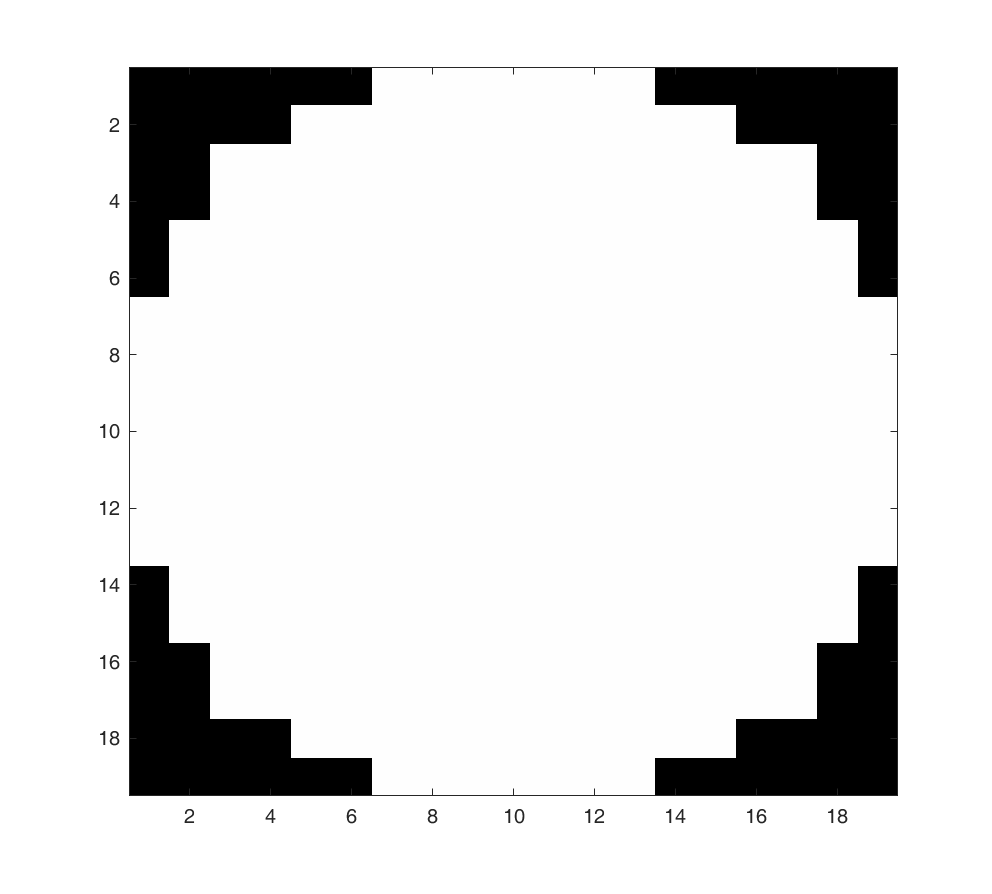

%% Question 1.3
% Observe the image -> most fruits in the image are circular
% Use disk-shaped structuring element (SE)
% Use "Image Segmenter" App to determine the size of SE
se = strel('disk', 10, 6); % create a SE with disk shape
colormap gray; image(se.Neighborhood * 255); % display the SE

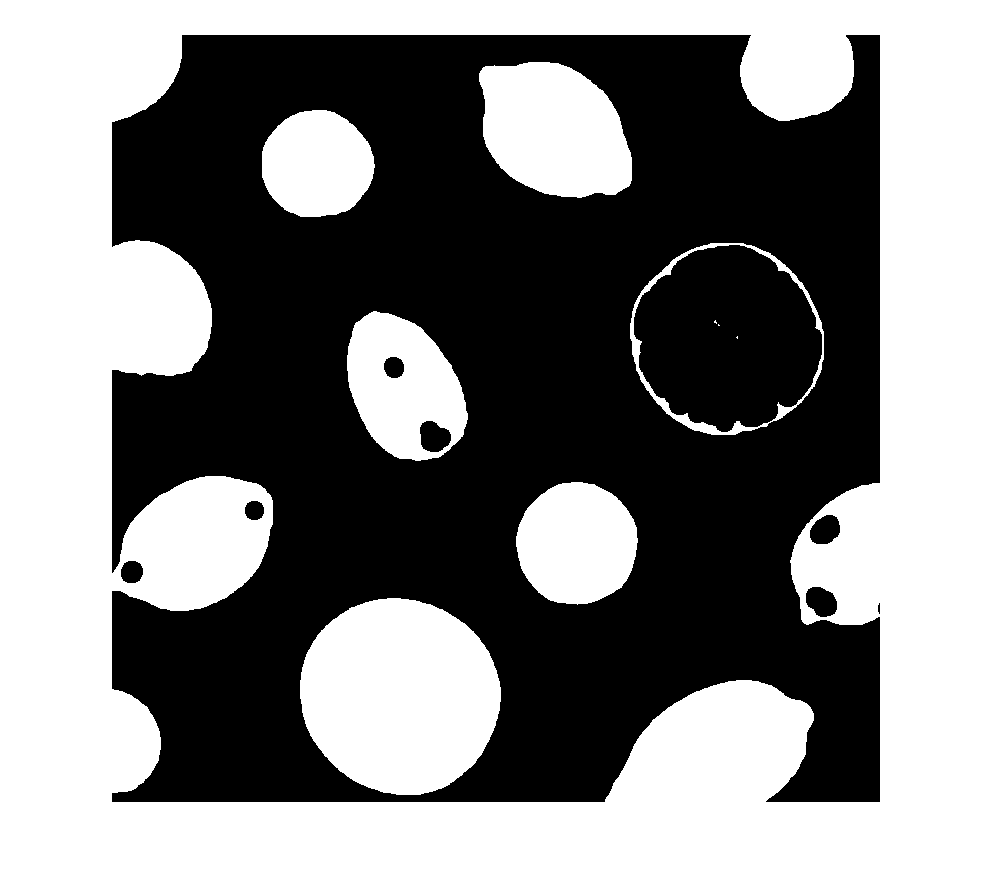

img_closed = imclose(img_diff2, se); % perform closing operation
img_closed2 = imerode(imdilate(img_diff2, se),se); % this line has similar effect to the previous line

imshow(img_closed); % display the results

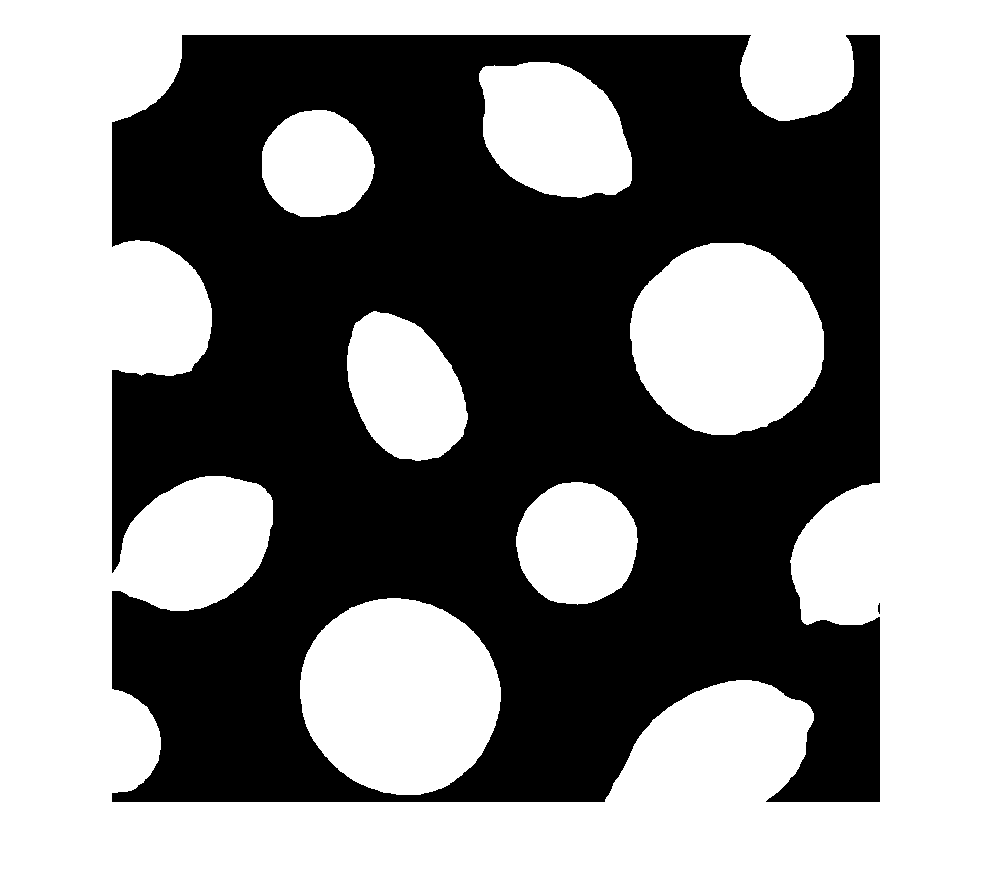


img_filled = imfill(img_closed, 'holes'); % fill all holes within the image
imshow(img_filled);

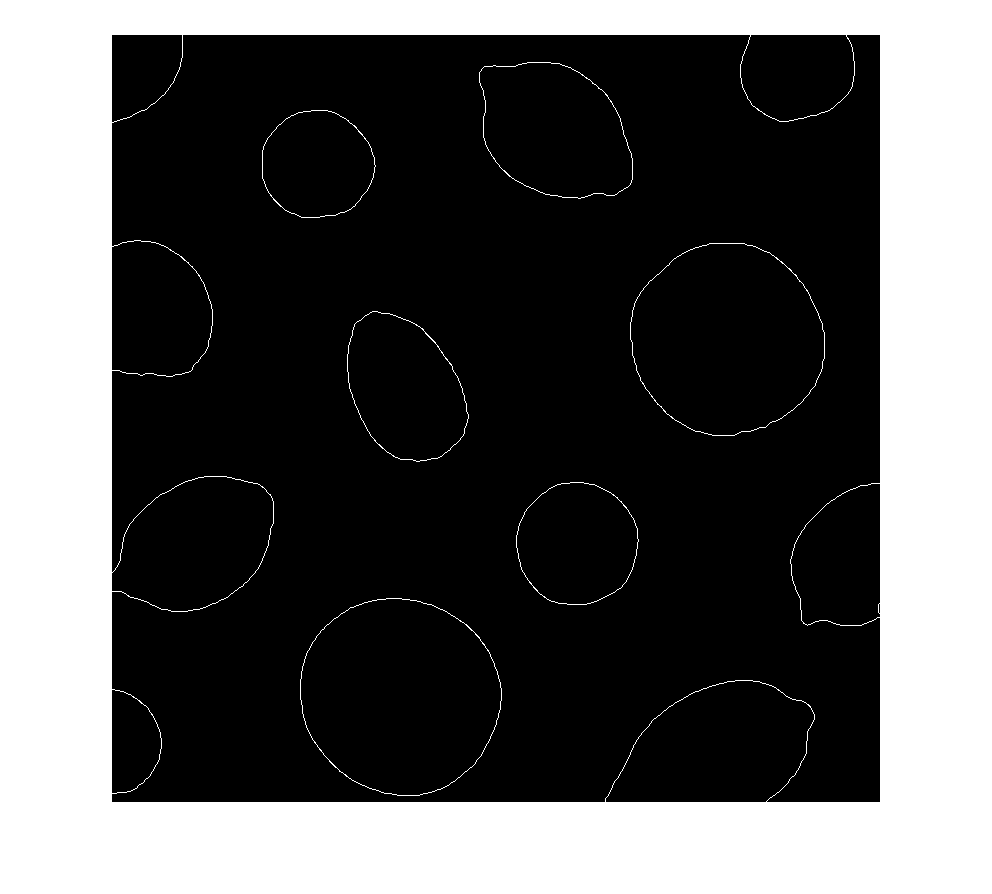

img_edge = edge(img_filled, 'sobel', 0.2); % perform edge detection now would give better result (not necessary)
imshow(img_edge);

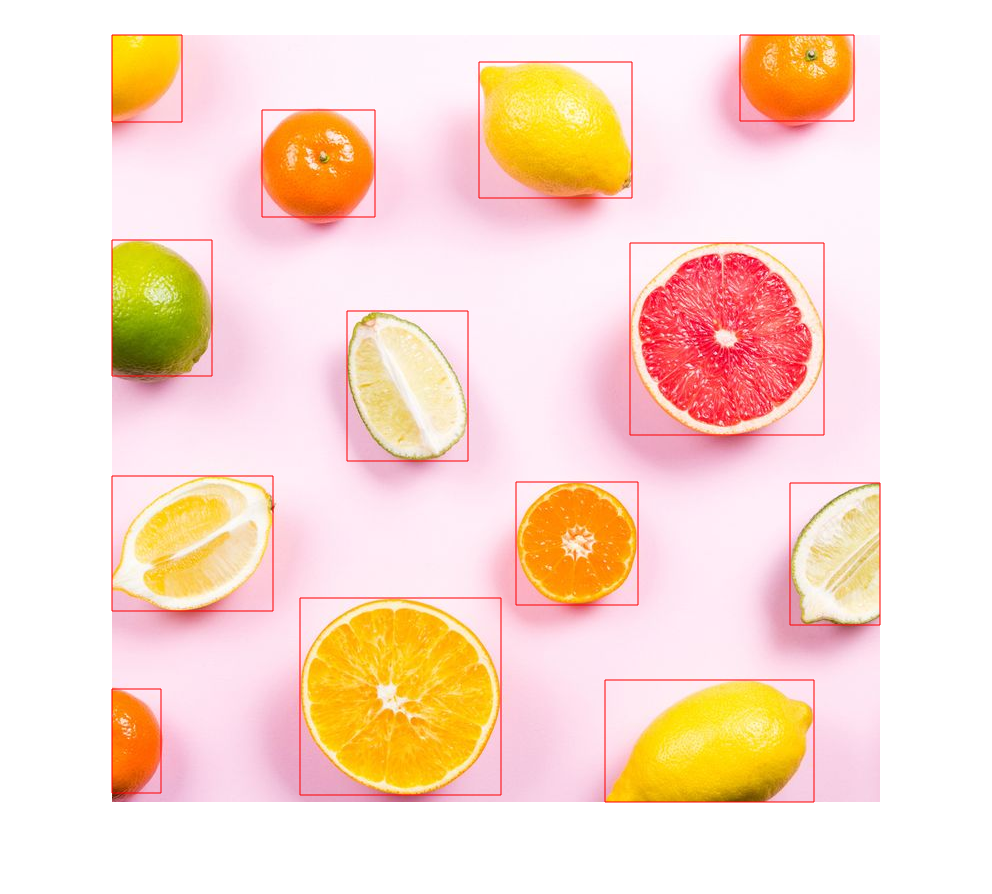

%% Question 1.4
regions = regionprops(img_filled, 'BoundingBox'); % calculate bounding box for each region
imshow(img_fruit); % display original image
hold on; % keep drawing on the same figure
for i = 1:numel(regions) % for each region
    rectangle('Position', regions(i).BoundingBox, 'edgecolor', 'red') % draw its bounding box as red rectangle
end
hold off; % draw the next plot in new figure

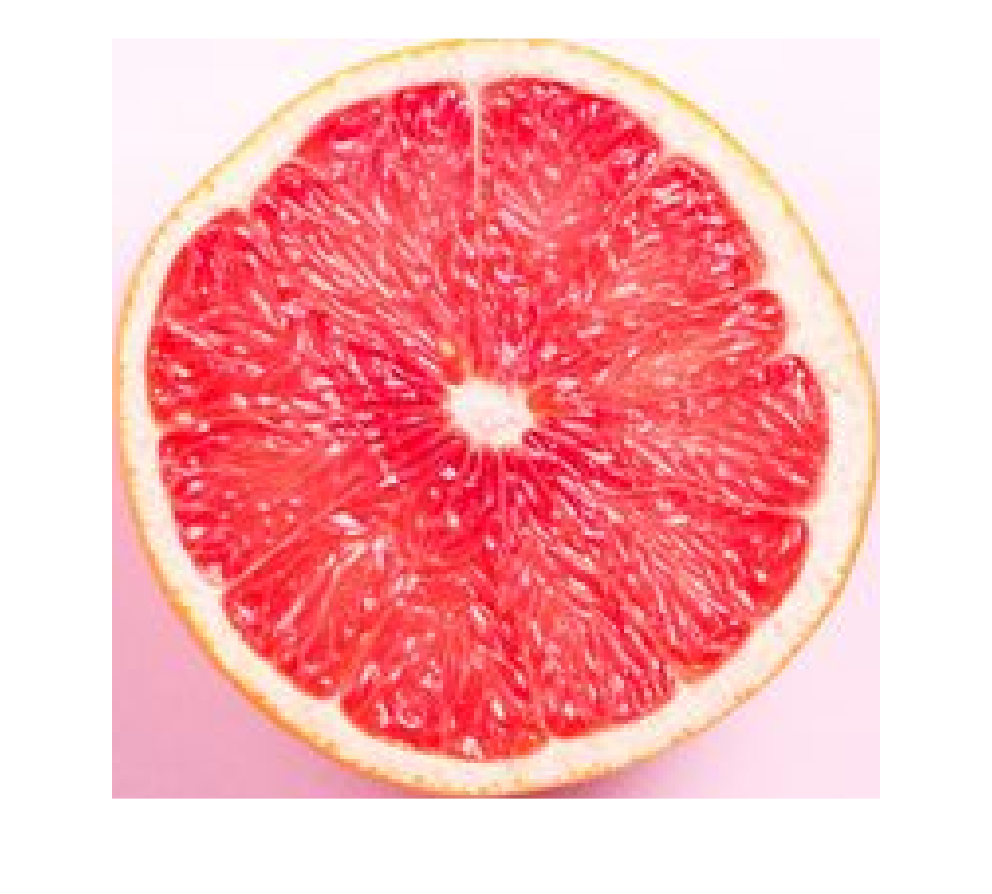

%% show the grapefruit
% investigate the index of grapefruit by the position of its bounding box
index = 11; % set the index of the graphfriut 
img_graphfruit = imcrop(img_fruit, regions(index).BoundingBox); % crop the image by the bounding box
imshow(img_graphfruit); % display the cropped image